clear; clc; close all;

fs = 44100;  
Ts = 1/fs;  
sinwa = [];

stim_ioi = 500

stim_ioi = 500

gap_int = 3

gap_int = 3

pha_init = 0

pha_init = 0

per_init = 600

per_init = 600


stim_seq = [repmat(stim_ioi,5,1)' stim_ioi*gap_int stim_ioi];

Wpha = 0.56

Wpha = 0.5600

Wper = 0.52

Wper = 0.5200

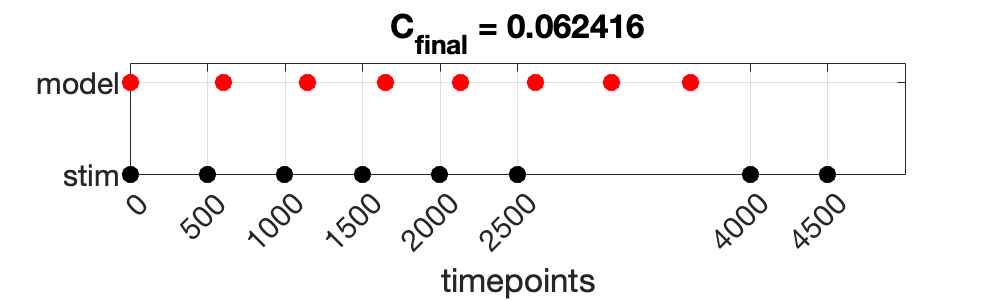


pha = NaN(length(stim_seq)+1,1)'; pha(1) = pha_init;
per = NaN(length(stim_seq)+1,1)'; per(1) = per_init;

chist = NaN(length(stim_seq)+1,1)'; 

% model stim seq loop -------------------
s = 1; % stim counter
m = 1; % model counter 
for i = 1:length(stim_seq)-1

    stim_vs_per = stim_seq(s)/per(m);
    nrep = floor(stim_vs_per);

    if nrep < 1 % normal model -- stim corresponds model 
    
        C = mod(mod(pha(m),1) + mod(stim_vs_per,1),1);
    
        if C > .5
            C = C - 1;
        end
        
        % normal model equations
        pha(m+1) = (1 - Wpha)*C;
        per(m+1) = (1 + Wper*C)*per(m);
        chist(m) = C;
           
        s = s+1;    % next stim index
        m = m+1;    % next model index
        
    else % if stim interval multiplies model interval (per(i))
        
        % find how many exact multiples 
        
        % model oscillates alone that many times
        
        % model doesn't correct for phase & period here (Wper = 0, Wpha =
        % 0)
        
    end
end


stim_seq_times = [0 cumsum(stim_seq)];
per_seq_times = [0 cumsum(per)];

figure;
plot(stim_seq_times, ones(length(stim_seq_times),1) , '.k', 'MarkerSize', 30)
hold on;
% plot(sinwa, 'linewidth', 1.5)

plot(per_seq_times, ones(length(per_seq_times),1)+.5 , '.r', 'MarkerSize', 30)

xticks(stim_seq_times); grid on; 
yticks([1 1.5]); yticklabels({'stim', 'model'});
% set(gca, 'YGrid', 'off', 'xlim', [-100 max(stim_seq_times)+100]);
set(gca,'XTickLabelRotation',45)
EK_plotlabels('timepoints', '', ['C_{final} = ' num2str(C)], 15);
set(gcf,'Position',[1500 500 500 150])

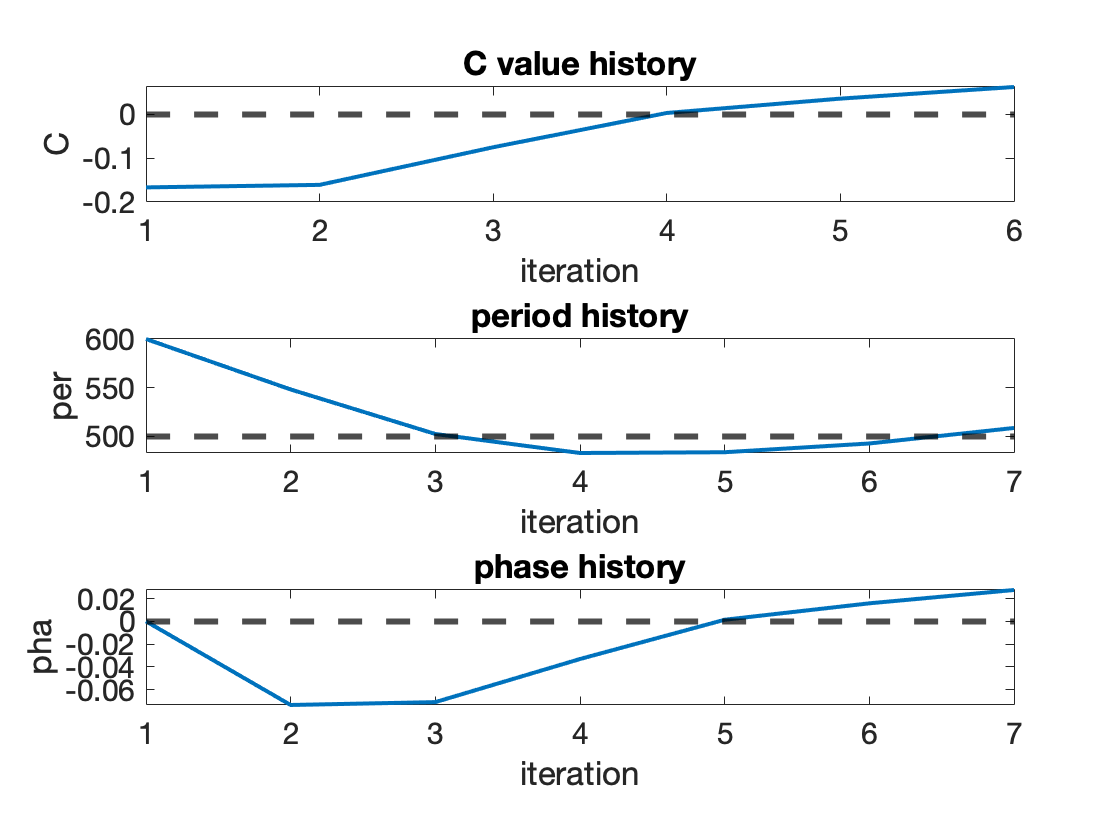


figure;
subplot(3,1,1)
plot(chist, 'LineWidth', 2); yline(0, '--k','LineWidth', 3) 
EK_plotlabels('iteration', 'C', 'C value history', 15);
subplot(3,1,2)
plot(per, 'LineWidth', 2); yline(stim_ioi, '--k','LineWidth', 3) 
EK_plotlabels('iteration', 'per', 'period history', 15);
subplot(3,1,3)
plot(pha, 'LineWidth', 2); yline(0, '--k','LineWidth', 3) 
EK_plotlabels('iteration', 'pha', 'phase history', 15);